# Z-transform and Frequency Response

## Exercise 1

**The z-transform is computed for the following sequences. For each sequence, all the values of **$z$ **that make the summation exist form a region of convergence (ROC) which is additionally provided.**

### **Sequence 1: **


$$x[n] = u[n-5]$$


*Using the Shift/Delay Property:*


$$X(z) = Z(x[n]) = Z(u[n-5]) = z^{-5}Z(u[n])$$


*Using the z-transform table:*

 
$$X(z) = z^{-5}Z(u[n]) = z^{-5}\frac{1}{1-z^{-1}} = \frac{z^{-5}}{1-z^{-1}} = \frac{1}{z^5-z^4}$$


*Since the shifting has no effect on the ROC, the region of convergence will therefore be *$|z| > 1$.

### **Sequence 2: **


$$x[n] = (-0.6)^nu[n]$$


*Using the z-transform table:*

 
$$X(z) = Z((-0.6)^nu[n]) = \frac{1}{1-(-0.6)z^{-1}} = \frac{1}{1+(0.6)z^{-1}} =  \frac{z}{z+0.6}$$


*The since the ROC is *$|z| > |-0.6|$*, the region of convergence can be simplified to *$|z| > 0.6$.

### **Sequence 3: **


$$x[n] = (-0.6)^n(u[n]-u[n-5])$$


*Note that *$u[n] - u[n-5]$* is equal to *$\delta[n] + \delta[n-1] + \delta[n-2] + \delta[n-3] + \delta[n-4]$

*The *$x[n]$* can therefore be simplified to *$x[n] = (-0.6)^n(\delta[n] + \delta[n-1] + \delta[n-2] + \delta[n-3] + \delta[n-4])$*. This equation shows that the *$x[n]$* is a right-sided, finite sequence and its ROC is expected to be of the form *$|z| > r$*. *

*Using the Linearity Property, the z-transform can be computed separately for *$(-0.6)^n(u[n])$* and *$-(-0.6)^n(u[n-5])$*. *


$$Z((-0.6)^n(u[n])) = \frac{z}{z+0.6}$$


*Using the Shift/Delay Property *$(-0.6)^n(u[n-5])$* can be transformed into:*


$$Z(-(-0.6)^n(u[n-5])) = -z^{-5}(-0.6)^{n+5}u[n] = -z^{-5}(-0.6)^5(-0.6)^{n}u[n] = -z^{-5}\frac{(-0.6)^5z}{z+0.6} = \frac{0.07776}{z^5+0.6z^4}$$



$$X(z) = \frac{z}{z+0.6} + \frac{0.07776}{z^5+0.6z^4}$$


*Since the z-transform is a power series, it converges when *$x[n]z^{-n}$* is absolutely summable (in other words:*$\sum_{n=-\infty}^{\infty}|x[n]z^{-n}| < \infty$*). Plugging the signal into the formula, the final ROC is all values of *$z$* except for *$|z|\neq 0$*. The detailed derivation can be seen below.*


$$$$\sum_{n=-\infty}^{\infty}{|x[n]z^{-n}}|<\infty$$
$$\sum_{n=-\infty}^{\infty}{|(-0.6)^n\left(u[n]-u[n-5]\right)z^{-n}}|<\infty$$
$$\sum_{n=-\infty}^{\infty}{|(-0.6z^{-1})^n\left(u[n]-u[n-5]\right)}|<\infty$$
$$\sum_{n=0}^{5}{|(-0.6z^{-1})^n}|<\infty$$
$$\sum_{n=0}^{5}{|\left(-\frac{0.6}{z}\right)^n}|<\infty$$$$


### **Sequence 4:**


$$x[n] = \alpha^nsin(\omega_0n)u[n]$$


*Using the z-transform table:*


$$X(z) = \frac{[\alpha sin(\omega_0)]z^{-1}}{1-[2\alpha cos(\omega_0)]z^{-1} + \alpha^2z^{-2}} = \frac{[\alpha sin(\omega_0)]z}{z^2-[2\alpha cos(\omega_0)]z + \alpha^2$$


*The ROC for this z-transform is *$|z| > \alpha$*.*

**Sources used to complete this section:**

- https://www.youtube.com/watch?v=Vu5PLKt2_LQ&t=183s&ab_channel=BarryVanVeen

- https://www.youtube.com/watch?v=4ZYlHTcdB8Q&ab_channel=BarryVanVeen

- [https://www.slideshare.net/geethannadurai/transforms-190210047](https://www.slideshare.net/geethannadurai/transforms-190210047)

- [https://www.youtube.com/watch?v=XJRW6jamUHk&ab_channel=MATLAB](https://www.youtube.com/watch?v=XJRW6jamUHk&ab_channel=MATLAB)

- [https://www.tutorialspoint.com/signals_and_systems/z_transforms_properties.htm](https://www.tutorialspoint.com/signals_and_systems/z_transforms_properties.htm)

- [https://www.youtube.com/watch?v=8fFnBAX8aeg&ab_channel=IainExplainsSignals%2CSystems%2CandDigitalComms](https://www.youtube.com/watch?v=8fFnBAX8aeg&ab_channel=IainExplainsSignals%2CSystems%2CandDigitalComms)

- [https://ocw.mit.edu/courses/6-003-signals-and-systhttps://timeseries.sci.muni.cz/index.php?pg=chapter-6--z-transformems-fall-2011/64490a008c1c5c25c86044351465abf7_MIT6_003F11_lec05.pdf](https://ocw.mit.edu/courses/6-003-signals-and-systems-fall-2011/64490a008c1c5c25c86044351465abf7_MIT6_003F11_lec05.pdf)

- https://timeseries.sci.muni.cz/index.php?pg=chapter-6--z-transform

## Exercise 2

**Below is a second-order FIR notch filter difference equation: **


$$y[n] = x[n] - x[n-1] + x[n-2]$$


### **Part 1: Computing the Transfer Function**

*Evaluating for the transfer function expression (in the z-domain) of the second-order FIR notch filter.*


$$y[n] = x[n] - x[n-1] + x[n-2] \\
Y(z) = X(z) - z^{-1} X(z)+ z^{-2}X(z) \\
Y(z) = X(z)\left(1 - z^{-1} + z^{-2}\right) \\
H(z) = \frac{Y(z)}{X(z)} = 1 - z^{-1} + z^{-2}$$


Multiplying by $1 = \frac{z^2}{z^2}$ the transfer function becomes $H(z) = \frac{Y(z)}{X(z)} = \frac{z^{2} - z^{1} + 1 }{z^2}$.

### **Part 2: Computing the Poles and Zeros**

*Computing the poles and zeros of *$H(z) = \frac{z^{2} - z^{1} + 1 }{z^2}$*.*

*The zeros of a transfer function are the values of *$z$* for which *$H(z) = 0$*, while the poles are the values of *$z$* for which *$H(z) = \infty$*. The transfer function is zero when the numerator is zero such that *$z^2-z^1+1 = 0$*. Using the formula *$z = \frac{-b \pm \sqrt{b^2 -4ac}}{2a}$*, the zeros of the *$H(z)$* occur when *$z = \frac{--1 \pm \sqrt{(-1)^2 -4(1)(1)}}{2(1)} = \frac{1 \pm \sqrt{-3}}{2} = \frac{1}{2}\pm j\frac{\sqrt3}{2}$*. The transfer function is *$\infty$* when the denominator is *$z^2=0$*, so *$H(z) = 0$* when *$z=0$*.*

### **Part 3: Drawing the Poles and Zeros in MATLAB**

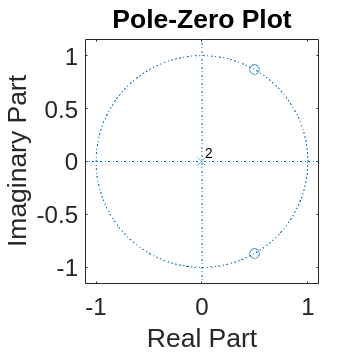

% Coefficients of the transfer function H(z)
zeros = [1, -1, 1]; % Numerator coefficients (zeros)
poles = [1, 0, 0]; % Denominator coefficients (poles)

figure('pos',[0,0,500,500],'DefaultAxesFontSize',18); 
zplane(zeros, poles);

### **Part 4: Proof Frequency Response**

*Showing that the frequency response of the second-order FIR notch filter can be written as *$H(e^{j\omega}) = e^{-j\omega}(2cos(\omega) - 1)$* using the identity *$cos(\omega) = \frac{e^{j\omega} + e^{-j\omega}}{2}$*. *

*The frequency response of the second-order FIR notch filter is derived below:*


$$y[n] = x[n] - x[n-1] + x[n-2]  \\
Y(\omega) = X(\omega) - e^{-j\omega}X(\omega) + e^{-2j\omega}X(\omega) \\
Y(\omega) = X(\omega) (1 - e^{-j\omega} + e^{-2j\omega}) \\ 
H(\omega) = \frac{Y(\omega)}{ X(\omega)} = (1 - e^{-j\omega} + e^{-2j\omega}) \\$$


*Multiplying *$H(\omega)$* by *$\frac{e^{-j\omega}}{e^{-j\omega}}$*:*


$$H(\omega) = \frac{e^{-j\omega}}{e^{-j\omega}}(1 - e^{-j\omega} + e^{-2j\omega}) = e^{-j\omega}( \frac{1}{e^{-j\omega}} -  \frac{e^{-j\omega}}{e^{-j\omega}}+  \frac{e^{-2j\omega}}{e^{-j\omega}}) = e^{-j\omega}(e^{j\omega} - 1 + e^{-j\omega}) = e^{-j\omega}(e^{j\omega} + e^{-j\omega} - 1)$$


*Using *$cos(\omega) = \frac{e^{j\omega} + e^{-j\omega}}{2}$* but slightly rearranged *$2cos(\omega) = e^{j\omega} + e^{-j\omega}$*:*


$$H(\omega) = e^{-j\omega}(e^{j\omega} + e^{-j\omega} - 1) = e^{-j\omega}(2cos(\omega) - 1)$$


### **Part 5: Proof Phase**

*Starting with the equation for the frequency response: *$H(\omega) = 1 - e^{-j\omega} + e^{-2j\omega}$* and using the identity *$e^{j\omega} = cos(\omega) + jsin(\omega)$*, the *$e^{j\omega}$* values inside *$H(\omega)$* can be replaced to show that *$\angle H(e^{j\omega}) = tan^{-1}\left(\frac{sin(\omega) - sin(2\omega)}{1 - cos(\omega) + cos(2\omega)} \right)$*. Additional properties such as the Even/Odd Property of trigonometric functions and the polar form are used. *


$$\begin{array}{rl}
H(\omega) = & 1 - e^{-j\omega} + e^{-2j\omega} \\
= & 1 - (\cos(-\omega) + j\sin(-\omega)) + (\cos(-2\omega) + j\sin(-2\omega)) \\
= & 1 - \cos(-\omega) - j\sin(-\omega) + \cos(-2\omega) + j\sin(-2\omega) \\
= & 1 - \cos(-\omega) + \cos(-2\omega) - j\sin(-\omega) + j\sin(-2\omega) \\
= & (1 - \cos(-\omega) + \cos(-2\omega)) + j(-\sin(-\omega) + \sin(-2\omega)) \\
= & (1 - \cos(\omega) + \cos(2\omega)) + j(\sin(\omega) - \sin(2\omega)) \\
\end{array}$$
 

*Using polar form to compute the angle where *$1 - cos(-\omega) + cos(-2\omega)$* is Real and *$j(sin(-\omega) - sin(-2\omega))$* is Imaginary:*


$$\angle H(e^{j\omega}) = \theta = tan^{-1}\left(\frac{Imaginary}{Real} \right) = tan^{-1}\left(\frac{sin(\omega) - sin(2\omega)}{1 - cos(\omega) + cos(2\omega)} \right)$$


### **Part 6: Determining Phase at Different Omega Values**

% Convert degrees to radians for the computation
omega1 = 59.999 * (pi / 180);
omega2 = 60.001 * (pi / 180);

% Compute phase angles in radians
phase1 = atan2(sin(omega1)-sin(2*omega1), 1-cos(omega1)+cos(2*omega1));
phase2 = atan2(sin(omega2)-sin(2*omega2), 1-cos(omega2)+cos(2*omega2));

% Convert phase angles from radians to degrees
phase1_deg = phase1 * (180 / pi);
phase2_deg = phase2 * (180 / pi);

% Compute the jump in phase near 60 degrees and check how close it is to 180 degrees
phase_jump = abs(phase2_deg-phase1_deg);
difference = abs(phase_jump-180);

fprintf('The phase at omega1 = %.3f degrees\n', phase1_deg);

The phase at omega1 = -59.999 degrees


fprintf('The phase at omega2 = %.3f degrees\n', phase2_deg);

The phase at omega2 = 119.999 degrees


fprintf('The jump in phase is %.3f degrees\n', phase_jump);

The jump in phase is 179.998 degrees


fprintf('The jump in phase is %.3f degrees close to 180\n', difference);

The jump in phase is 0.002 degrees close to 180


### **Part 7: Drawing the Magnitude and Phase of the Frequency Response**

*The magnitude and phase plots show the expected linear phase of a FIR filter, with a 180 phase jump when the frequency crosses the zero, similar to what was observed in the analytical results.*

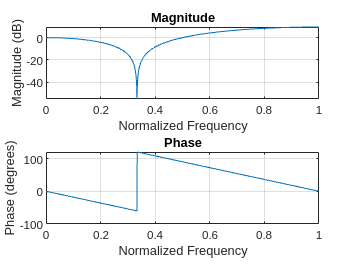

% Define the filter coefficients
b = [1 -1 1]; 
a = 1; 

[h, w] = freqz(b, a, 1024); 

% Plot the magnitude response in decibels (dB)
figure;
subplot(2,1,1); 
plot(w/pi, 20*log10(abs(h))); % Normalize frequency by pi and convert magnitude to dB
title('Magnitude');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
grid on;

% Plot the phase response in degrees
subplot(2,1,2);
plot(w/pi, angle(h)*(180/pi)); % Convert phase angle to degrees
title('Phase');
xlabel('Normalized Frequency');
ylabel('Phase (degrees)');
grid on;

**Sources used to complete this section:**

- [https://www.youtube.com/watch?v=IJhyJGjeLvA&ab_channel=DrWaleedAl-Nuaimy](https://www.youtube.com/watch?v=IJhyJGjeLvA&ab_channel=DrWaleedAl-Nuaimy)

- [https://www.youtube.com/watch?v=Vu5PLKt2_LQ&ab_channel=BarryVanVeen](https://www.youtube.com/watch?v=Vu5PLKt2_LQ&ab_channel=BarryVanVeen)

- [https://dsp.stackexchange.com/questions/9138/finding-the-frequency-response-of-a-filter-defined-as-a-z-domain-transfer-functi](https://dsp.stackexchange.com/questions/9138/finding-the-frequency-response-of-a-filter-defined-as-a-z-domain-transfer-functi)

## Exercise 3

**The following information is known about a linear time-invariant system:**

    **a) The system is causal.**

    **b) When the input signal x[n] is **$x[n] = -\frac{1}{3}\left(\frac{1}{2}\right)^nu[n] - \frac{4}{3}(2)^nu[-n-1]$**, the output signal is **$y[n]$**. **

**It is known that the z-transform of **$y[n]$ **is **$Y(z) = \frac{1-z^{-2}}{(1-\frac{1}{2}z^{-1})(1-2z^{-1}) $.

### Part 1: Z-Transform and ROC

**Computing the **$X(z)$**, the z-transform of **$x[n]$**, and specifying its region of converge below.**

*Using the Linearity Property, the *$-\frac{1}{3}\left(\frac{1}{2}\right)^nu[n]$* and *$- \frac{4}{3}(2)^nu[-n-1]$* parts of *$x[n]$* can be used to compute the z-trasnform separately before combining. *

*Taking the z-transform of *$-\frac{1}{3}\left(\frac{1}{2}\right)^nu[n]$* can be done by using the property *$Aa^nu[n] = \frac{A}{1-az^{-1}} = \frac{Az}{z-a}$* and ROC is *$|z| > |a|$*:*

$Z(-\frac{1}{3}\left(\frac{1}{2}\right)^nu[n]) = \frac{-\frac{1}{3}}{1-\frac{1}{2}z^{-1}} = \frac{-\frac{1}{3}z}{z-\frac{1}{2}} = -\frac{z}{3(z-\frac{1}{2})}$* with an ROC is *$|z|> |\frac{1}{2}|$

*Taking the z-transform of *$- \frac{4}{3}(2)^nu[-n-1]$* can be done by using the property *$Aa^nu[-n-1] = \frac{-A}{1-az^{-1}} = \frac{-Az}{z-a}$* and ROC is *$|z| < |a|$*:*

$Z(- \frac{4}{3}(2)^nu[-n-1]) = -\frac{-\frac{4}{3}}{1-2z^{-1}} = \frac{\frac{4}{3}z}{z-2} = \frac{4z}{3(z-2)}$* with an ROC *$|z|< |2|$

*The combined *$X(z) = -\frac{z}{3(z-\frac{1}{2})} +  \frac{4z}{3(z-2)}$* with an ROC equal to *$|z|> |\frac{1}{2}| \cap |z|< |2|$* so ROC is *$\frac{1}{2} < |z| < 2$*. *

### **Part 2: Inverse Z-Transform**

*Since the numerator degree is higher than the denominator, long division must be performed to convert the fraction into a form that can be simplified using partial fraction decomposition.*


$$Y(z)=\frac{1-z^{-2}}{\left(1-\frac{1}{2}z^{-1}\right)\left(1-2z^{-1}\right)}$$


*After performing long division the new *$Y(z)$*can be simplified further:*


$$Y(z)=-1+2\frac{1-\frac{5}{4}z^{-1}}{\left(1-\frac{1}{2}z^{-1}\right)\left(1-2z^{-1}\right)}$$



$$\frac{1-\frac{5}{4}z^{-1}}{\left(1-\frac{1}{2}z^{-1}\right)\left(1-2z^{-1}\right)}=\frac{A}{1-\frac{1}{2}z^{-1}}+\frac{B}{1-2z^{-1}} \\
1-\frac{5}{4}z^{-1}=A\left(1-2z^{-1}\right)+B\left(1-\frac{1}{2}z^{-1}\right) \\
1-\frac{5}{4}z^{-1}=A-A2z^{-1}+B-B\frac{1}{2}z^{-1}$$



$$1=A+B \\
-\frac{5}{4}z^{-1}=-A2z^{-1}-B\frac{1}{2}z^{-1}\Longleftrightarrow5=8A+2B$$


*The linear system can be solved for values of A and B:*


$$\left[\matrix{
1 & 1 \cr
8 & 2
}\right]
\left[\matrix{A \cr B}\right]=\left[\matrix{1 \cr 5}\right]$$



$$det(M)=1*2-1*8=-6\\
det(M_A)=1*2-1*5=-3\\
det(M_B)=1*5-1*8=-3\\
A=\frac{-3}{-6}=\frac{1}{2}\\
B=\frac{-3}{-6}=\frac{1}{2}$$



$$$$\frac{1-\frac{5}{4}z^{-1}}{\left(1-\frac{1}{2}z^{-1}\right)\left(1-2z^{-1}\right)}=\frac{1}{2}\frac{1}{1-\frac{1}{2}z^{-1}}+\frac{1}{2}\frac{1}{1-2z^{-1}}$$

$$Y(z)=-1+\frac{1}{1-\frac{1}{2}z^{-1}}+\frac{1}{1-2z^{-1}}$$$$


*Based on the new *$Y(z)$*, the possible values of ROC with there inverse z-transform are shown below:*

ROC is $|z|> |\frac{1}{2}| \cap |z|> |2|$


$$y[n]=-\delta[n]+\left(\frac{1}{2}\right)^nu[n]+(2)^nu[n]$$


ROC is $|z|> |\frac{1}{2}| \cap |z|< |2|$


$$y[n]=-\delta[n]+\left(\frac{1}{2}\right)^nu[n]-(2)^nu[-n-1]$$


ROC is $|z|< |\frac{1}{2}| \cap |z|> |2|$


$$y[n]=-\delta[n]-\left(\frac{1}{2}\right)^nu[-n-1]+(2)^nu[n]$$


ROC is $|z|> |\frac{1}{2}| \cap |z|> |2|$


$$y[n]=-\delta[n]-\left(\frac{1}{2}\right)^nu[-n-1]]-(2)^nu[-n-1]$$
    

*Since the system is causal, the ROC found in Part 1 for*$X(z)$* must be the same for *$Y(z)$*. Identifying the inverse z-transform with an ROC of *$|z|> |\frac{1}{2}| \cap |z|< |2|$* from the above formulas, the following solution would therefore be chosen to represent *$y[n]$:


$$y[n]=-\delta[n]+\left(\frac{1}{2}\right)^nu[n]-(2)^nu[-n-1]$$


### Part 3: Impulse Response

*To compute the impulse response of the system, the corresponding transfer function *$H(z) = \frac{Y(z)}{X(z)}$* must first be derived using the calculations from the previous sections.*

*Simplifying *$X(z)$* such that:*$X(z) = \frac{-\frac{1}{3}}{(1-\frac{1}{2}z^{-1})} + \frac{\frac{4}{3}}{(1-2z^{-1})} = \frac{-\frac{1}{3}(1-2z^{-1})}{(1-\frac{1}{2}z^{-1})} + \frac{\frac{4}{3}(1-\frac{1}{2}z^{-1})}{(1-2z^{-1})} = \frac{-\frac{1}{3} + \frac{2}{3}z^{-1} + \frac{4}{3} - \frac{2}{3}z^{-1}}{((1-\frac{1}{2}z^{-1})(1-2z^{-1})} = \frac{1}{(1-\frac{1}{2}z^{-1})(1-2z^{-1})|$

*Computing *$H(z)$*:*


$$H(z) = \frac{Y(z)}{X(z)} = \frac{\frac{1-z^{-2}}{\left(1-\frac{1}{2}z^{-1}\right)\left(1-2z^{-1}\right)}}{\frac{1}{(1-\frac{1}{2}z^{-1})(1-2z^{-1})}} = 1 - z^{-2}$$


*Using the inverse z-tranform table where *$A = A\delta[n]$* and *$Az^{-n_0} = A\delta[n-n_0]$* the impulse response is therefore:*


$$h[n] = 1 - z^{-2} = \delta[n] - \delta[n-2]$$


**Sources used to complete this section:**

- [https://dsp.stackexchange.com/questions/87041/finding-the-inverse-z-transform](https://dsp.stackexchange.com/questions/87041/finding-the-inverse-z-transform)

- [https://www.symbolab.com/solver/polynomial-long-division-calculator/long%20division%20%5Cfrac%7B1-x%5E%7B2%7D%7D%7Bx%5E%7B2%7D-2.5x%2B1%7D?or=input](https://www.symbolab.com/solver/polynomial-long-division-calculator/long%20division%20%5Cfrac%7B1-x%5E%7B2%7D%7D%7Bx%5E%7B2%7D-2.5x%2B1%7D?or=input)

- [https://www.maplesoft.com/content/EngineeringFundamentals/10/MapleDocument_10/Transfer%20Functions,%20Poles%20and%20Zeros.pdf](https://www.maplesoft.com/content/EngineeringFundamentals/10/MapleDocument_10/Transfer%20Functions,%20Poles%20and%20Zeros.pdf)

- [https://www.quora.com/Is-the-impulse-response-of-a-function-the-same-as-the-inverse-of-the-Laplace-transform](https://www.quora.com/Is-the-impulse-response-of-a-function-the-same-as-the-inverse-of-the-Laplace-transform)

- https://dsp.stackexchange.com/questions/87041/finding-the-inverse-z-transform